### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')


### Calculate oxygen sensor lag for CTD alignment 

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year7')

% Casts 
cast01 = readSBScnv( 'ar46_001_hyst.cnv' );
cast02 = readSBScnv( 'ar46_002_hyst.cnv' );
cast03 = readSBScnv( 'ar46_003_hyst.cnv' );
cast04 = readSBScnv( 'ar46_004_hyst.cnv' );
cast05 = readSBScnv( 'ar46_005_hyst.cnv' );
cast06 = readSBScnv( 'ar46_006_hyst.cnv' );
cast07 = readSBScnv( 'ar46_007_hyst.cnv' );
cast08 = readSBScnv( 'ar46_008_hyst.cnv' );
cast09 = readSBScnv( 'ar46_009_hyst.cnv' );
cast10 = readSBScnv( 'ar46_010_hyst.cnv' );
cast11 = readSBScnv( 'ar46_011_hyst.cnv' );
cast12 = readSBScnv( 'ar46_012_hyst.cnv' );
cast13 = readSBScnv( 'ar46_013_hyst.cnv' );
cast14 = readSBScnv( 'ar46_014_hyst.cnv' );
cast15 = readSBScnv( 'ar46_015_hyst.cnv' );
cast16 = readSBScnv( 'ar46_016_hyst.cnv' );
cast17 = readSBScnv( 'ar46_017_hyst.cnv' );
cast18 = readSBScnv( 'ar46_018_hyst.cnv' );
cast19 = readSBScnv( 'ar46_019_hyst.cnv' );

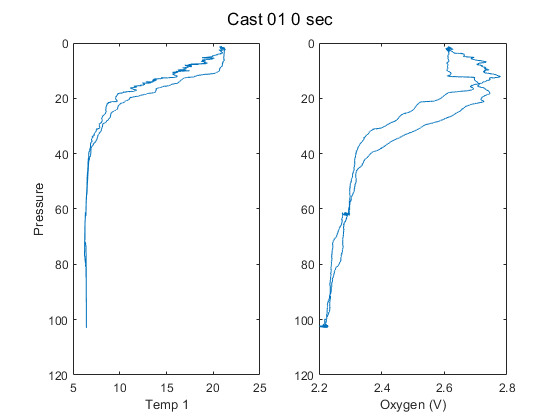

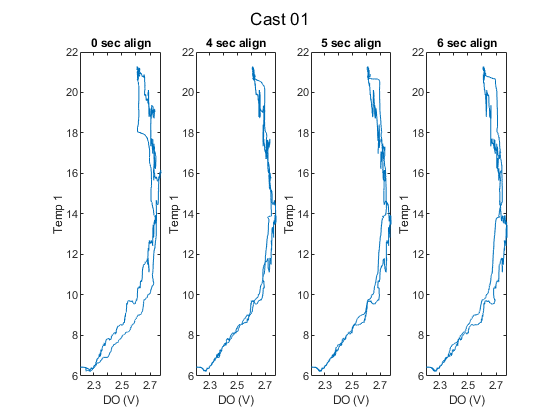

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 5; a3 = 6;
cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

CTD_sen1 = 1; % Use primary or secondary CTD temp and sal
CTD_sen2 = 2; 

cast01 = align_CTD_by_sensor_KF(cast01,'Cast 01',a1,a2,a3,CTD_sen1);

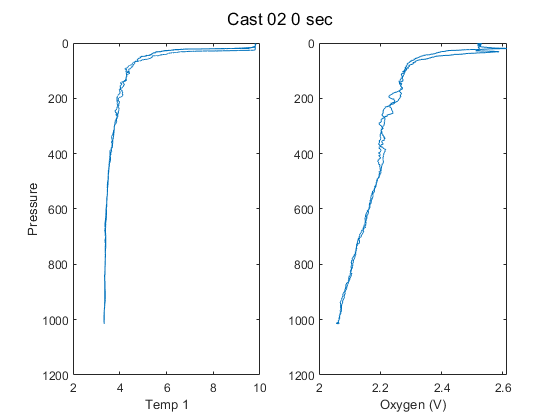

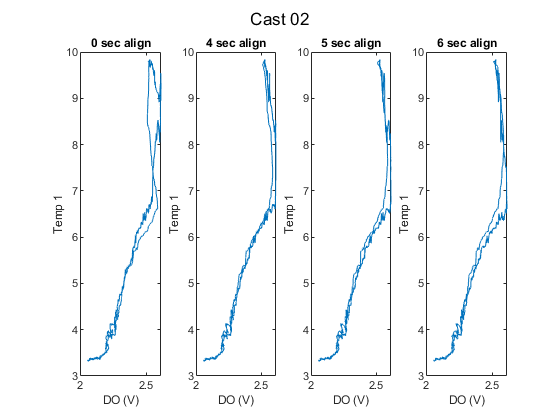

cast02 = align_CTD_by_sensor_KF(cast02,'Cast 02',a1,a2,a3,CTD_sen1);

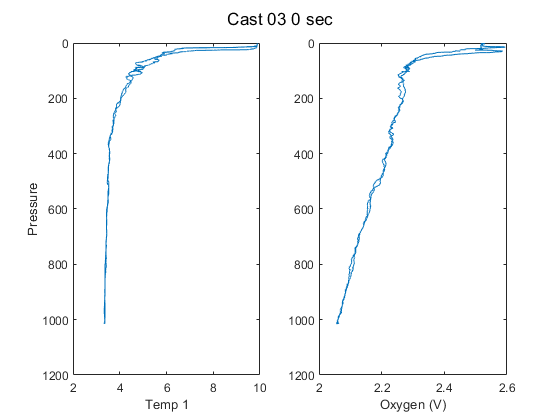

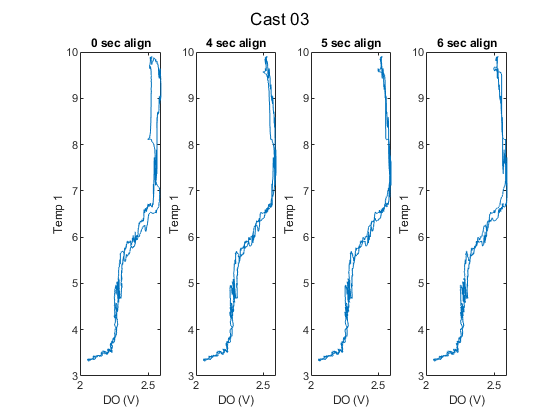

cast03 = align_CTD_by_sensor_KF(cast03,'Cast 03',a1,a2,a3,CTD_sen1);

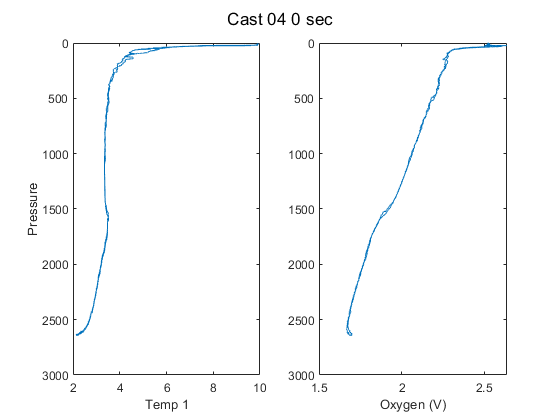

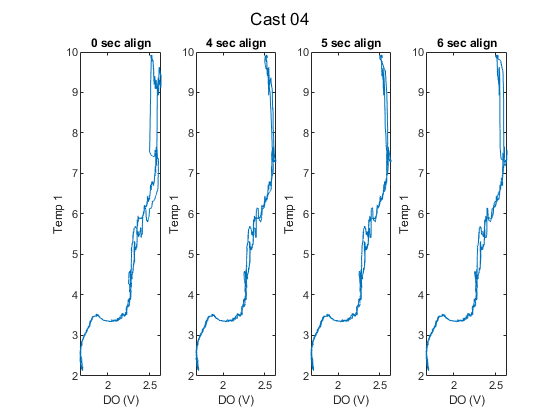

cast04 = align_CTD_by_sensor_KF(cast04,'Cast 04',a1,a2,a3,CTD_sen1);

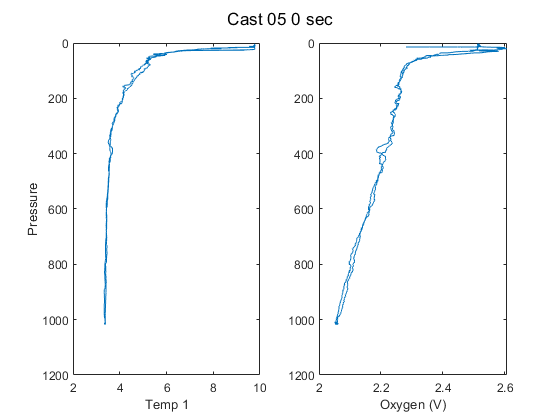

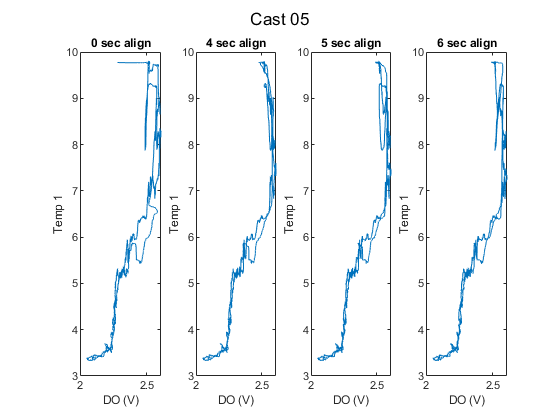

cast05 = align_CTD_by_sensor_KF(cast05,'Cast 05',a1,a2,a3,CTD_sen1);

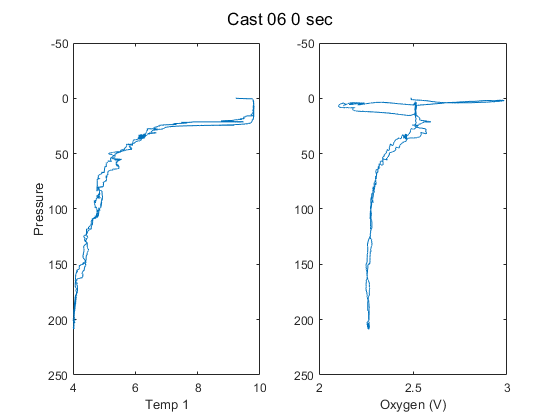

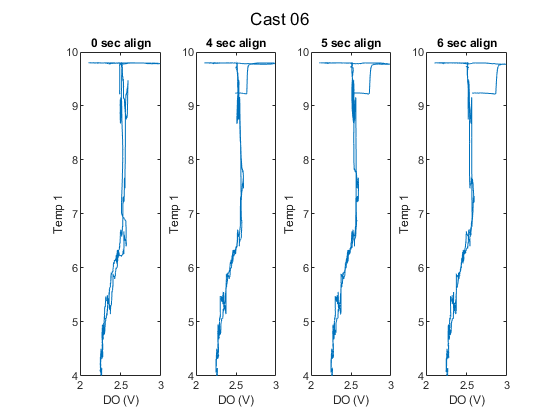

cast06 = align_CTD_by_sensor_KF(cast06,'Cast 06',a1,a2,a3,CTD_sen1);

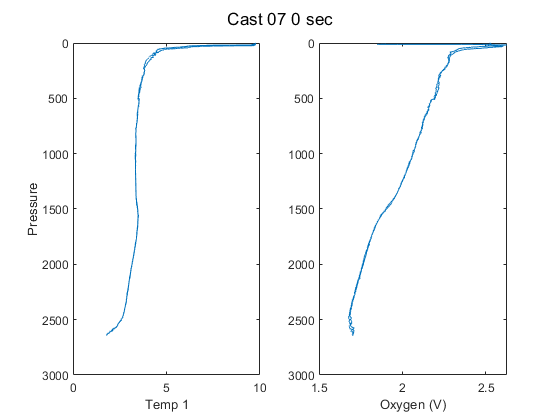

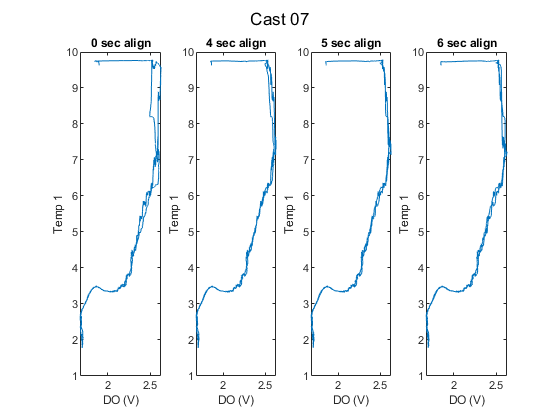

cast07 = align_CTD_by_sensor_KF(cast07,'Cast 07',a1,a2,a3,CTD_sen1);

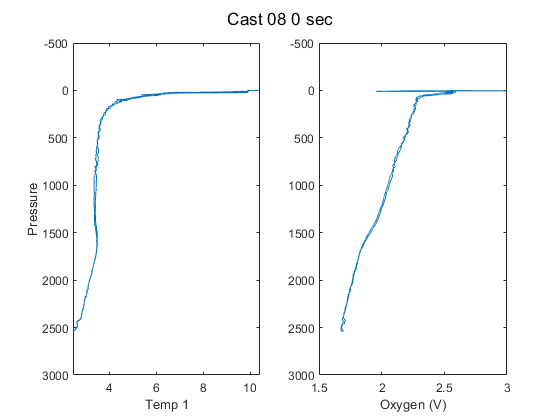

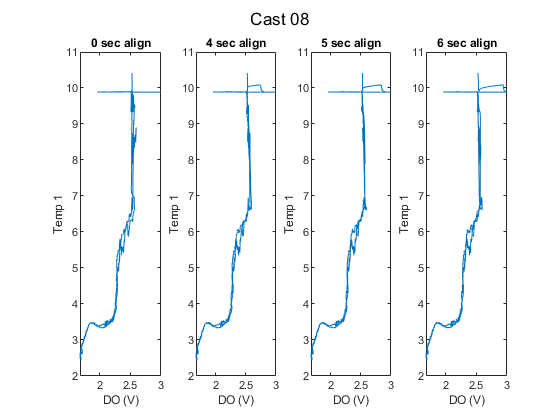

cast08 = align_CTD_by_sensor_KF(cast08,'Cast 08',a1,a2,a3,CTD_sen1);

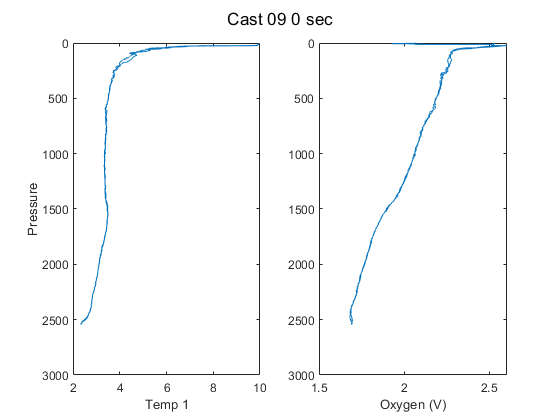

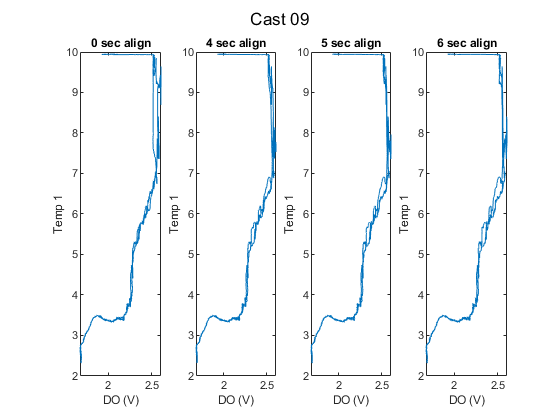

cast09 = align_CTD_by_sensor_KF(cast09,'Cast 09',a1,a2,a3,CTD_sen1);

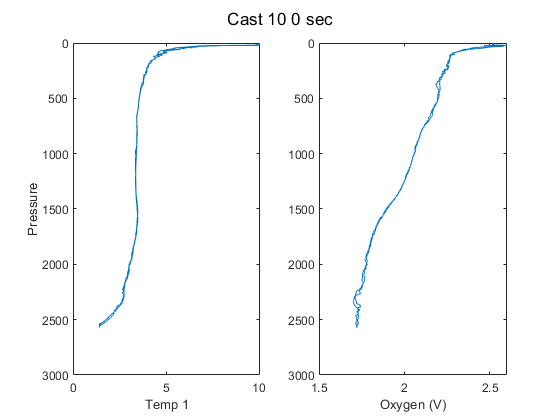

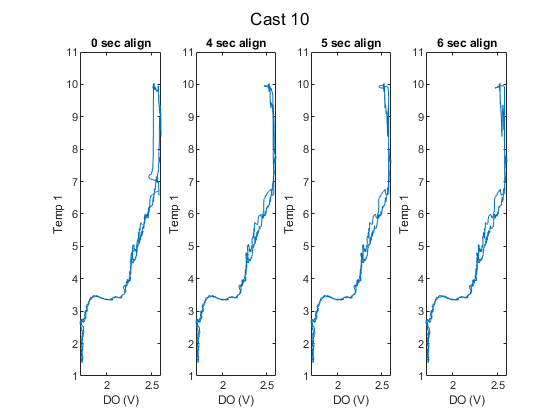

cast10 = align_CTD_by_sensor_KF(cast10,'Cast 10',a1,a2,a3,CTD_sen1);

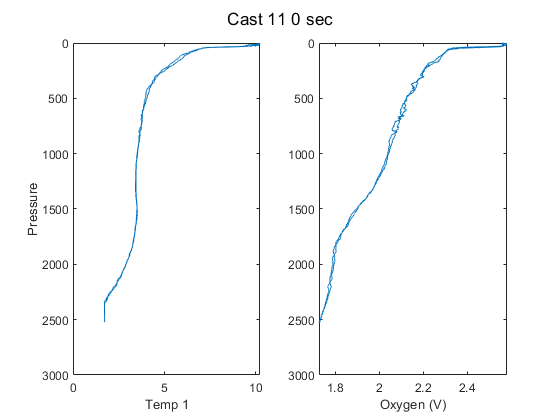

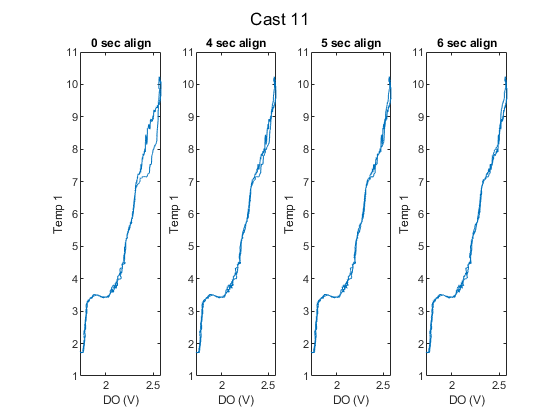

cast11 = align_CTD_by_sensor_KF(cast11,'Cast 11',a1,a2,a3,CTD_sen1);

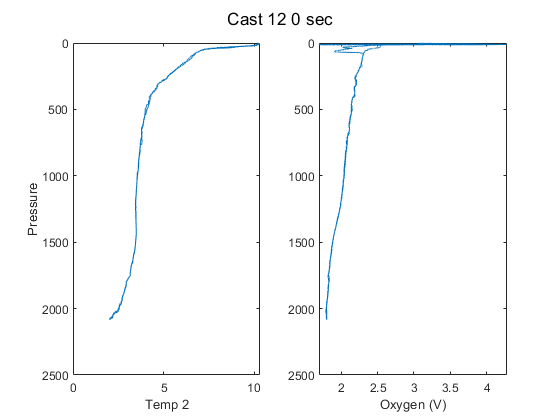

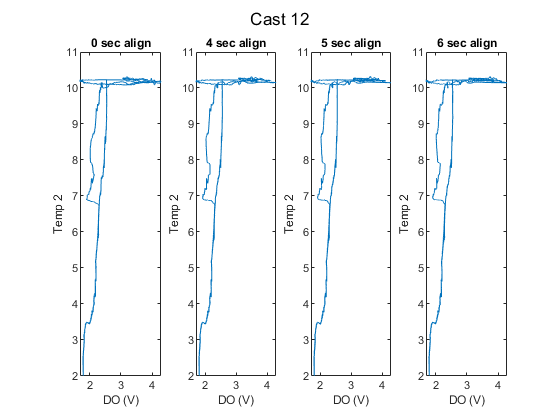

cast12 = align_CTD_by_sensor_KF(cast12,'Cast 12',a1,a2,a3,CTD_sen2);

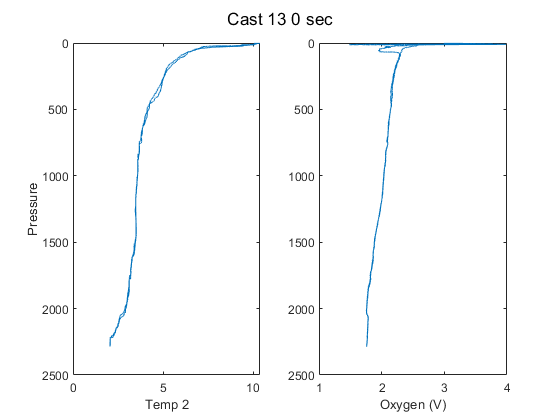

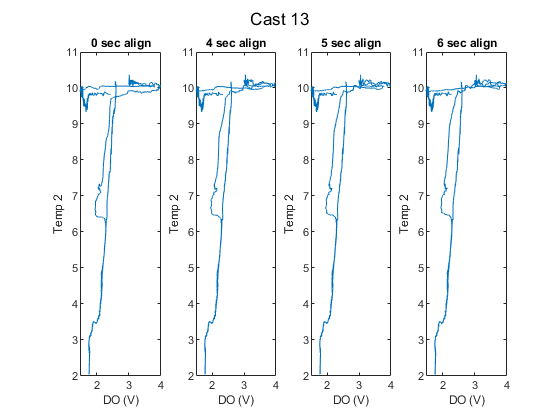

cast13 = align_CTD_by_sensor_KF(cast13,'Cast 13',a1,a2,a3,CTD_sen2);

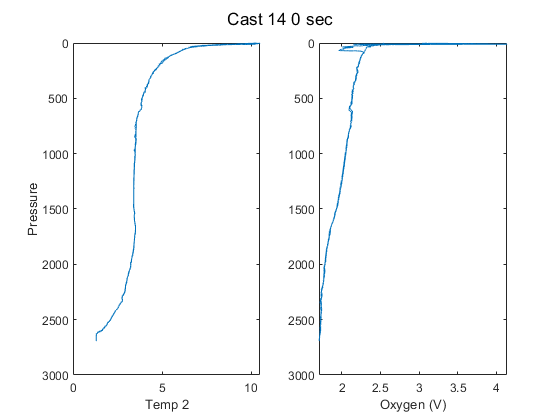

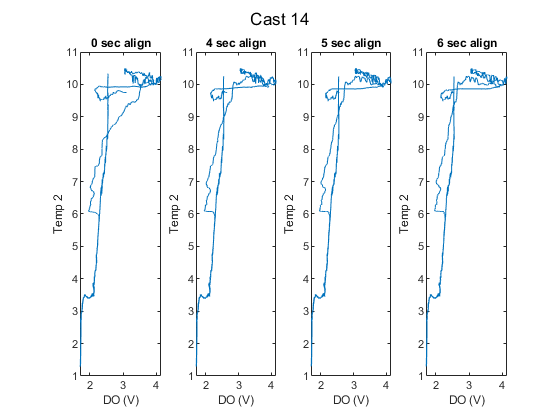

cast14 = align_CTD_by_sensor_KF(cast14,'Cast 14',a1,a2,a3,CTD_sen2);

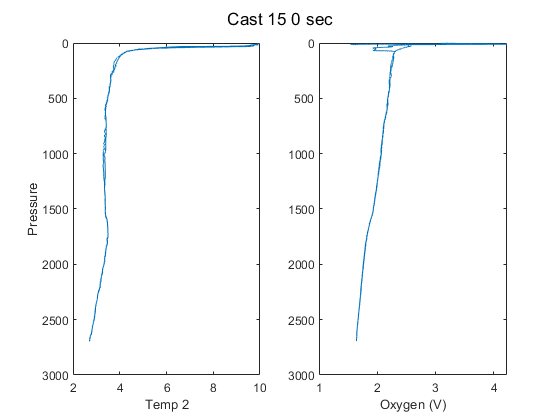

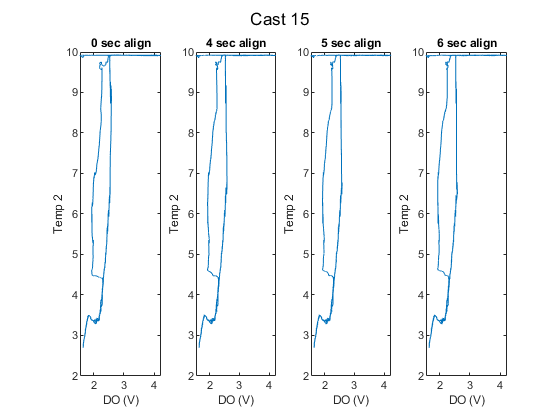

cast15 = align_CTD_by_sensor_KF(cast15,'Cast 15',a1,a2,a3,CTD_sen2);

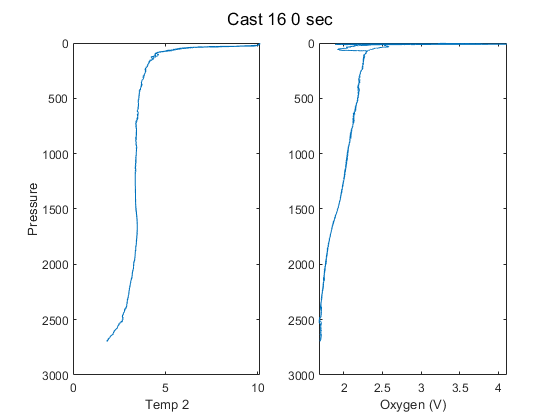

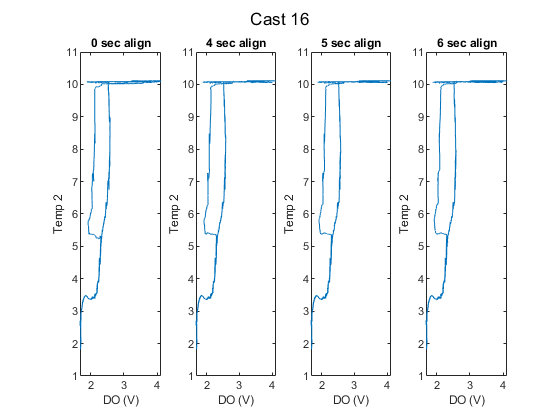

cast16 = align_CTD_by_sensor_KF(cast16,'Cast 16',a1,a2,a3,CTD_sen2);

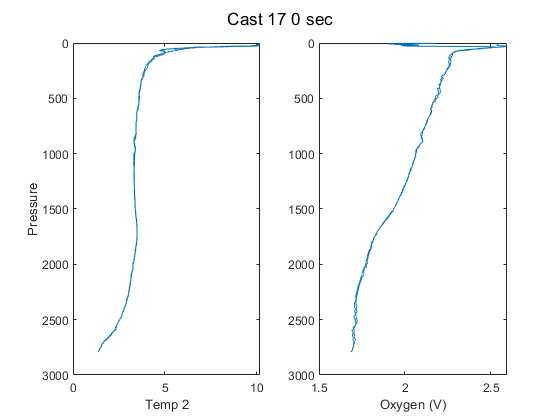

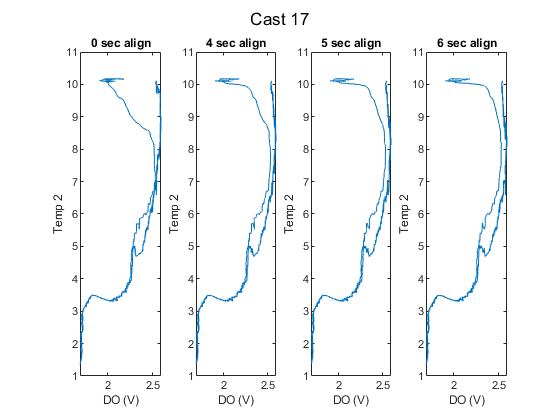

cast17 = align_CTD_by_sensor_KF(cast17,'Cast 17',a1,a2,a3,CTD_sen2);

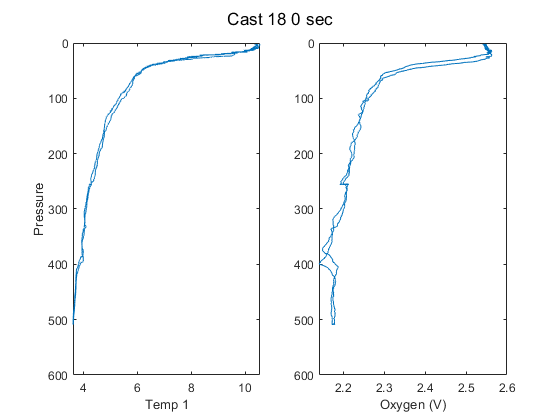

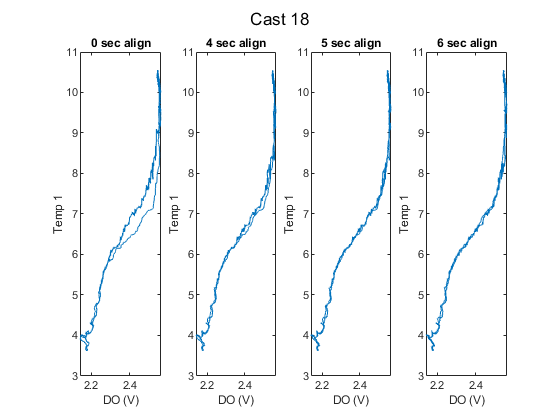

cast18 = align_CTD_by_sensor_KF(cast18,'Cast 18',a1,a2,a3,CTD_sen1);

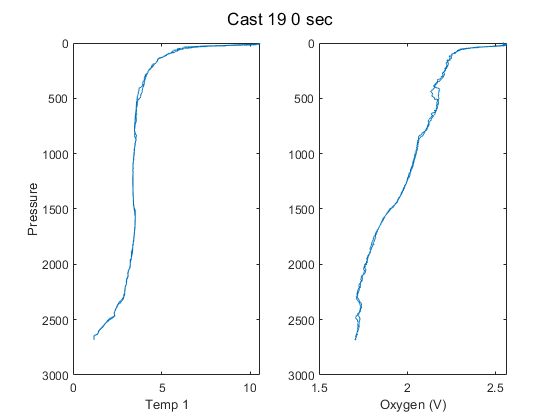

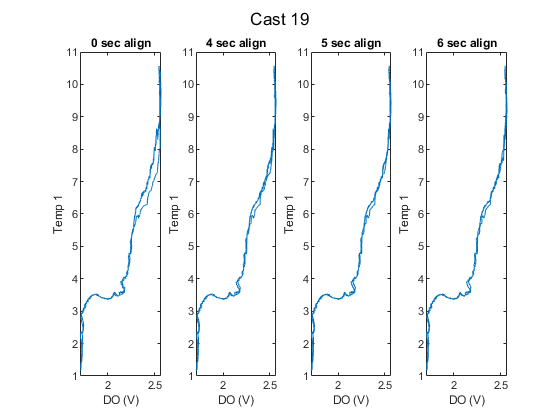

cast19 = align_CTD_by_sensor_KF(cast19,'Cast 19',a1,a2,a3,CTD_sen1);


% Pick align_sec

a1 = 5;
align_sec = a1; 

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 



% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year7')
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year7\From_Leah')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year7')

btl = readtable('Irminger_Sea-09_ar46_CTD_Sampling_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum01 = btl(btl.Cast == 1,:);
btlsum02 = btl(btl.Cast == 2,:);
btlsum03 = btl(btl.Cast == 3,:);
btlsum04 = btl(btl.Cast == 4,:);
btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:); 
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);
btlsum13 = btl(btl.Cast == 13,:);
btlsum14 = btl(btl.Cast == 14,:);
btlsum16 = btl(btl.Cast == 16,:); 
btlsum17 = btl(btl.Cast == 17,:);
btlsum18 = btl(btl.Cast == 18,:);
btlsum19 = btl(btl.Cast == 19,:);

% [btlsum] = combine_btl_files(leah_btl_file,btl_file,btlsum,CTD_sen)
btlsum01 = combine_btl_files('ar46_001.cbot_s','ar46_001.csv',btlsum01,CTD_sen1);
btlsum02 = combine_btl_files('ar46_002.cbot_s','ar46_002.csv',btlsum02,CTD_sen1);
btlsum03 = combine_btl_files('ar46_003.cbot_s','ar46_003.csv',btlsum03,CTD_sen1);
btlsum04 = combine_btl_files('ar46_004.cbot_s','ar46_004.csv',btlsum04,CTD_sen1);
btlsum05 = combine_btl_files('ar46_005.cbot_s','ar46_005.csv',btlsum05,CTD_sen1);
btlsum06 = combine_btl_files('ar46_006.cbot_s','ar46_006.csv',btlsum06,CTD_sen1);
btlsum07 = combine_btl_files('ar46_007.cbot_s','ar46_007.csv',btlsum07,CTD_sen1);
btlsum08 = combine_btl_files('ar46_008.cbot_s','ar46_008.csv',btlsum08,CTD_sen1);
btlsum09 = combine_btl_files('ar46_009.cbot_s','ar46_009.csv',btlsum09,CTD_sen1);
btlsum10 = combine_btl_files('ar46_010.cbot_s','ar46_010.csv',btlsum10,CTD_sen1);
btlsum11 = combine_btl_files('ar46_011.cbot_s','ar46_011.csv',btlsum11,CTD_sen1);
btlsum12 = combine_btl_files('ar46_012.cbot_s','ar46_012.csv',btlsum12,CTD_sen2);
btlsum13 = combine_btl_files('ar46_013.cbot_s','ar46_013.csv',btlsum13,CTD_sen2);
btlsum14 = combine_btl_files('ar46_014.cbot_s','ar46_014.csv',btlsum14,CTD_sen2);
btlsum16 = combine_btl_files('ar46_016.cbot_s','ar46_016.csv',btlsum16,CTD_sen2);
btlsum17 = combine_btl_files('ar46_017.cbot_s','ar46_017.csv',btlsum17,CTD_sen2);
btlsum18 = combine_btl_files('ar46_018.cbot_s','ar46_018.csv',btlsum18,CTD_sen1);
btlsum19 = combine_btl_files('ar46_019.cbot_s','ar46_019.csv',btlsum19,CTD_sen1);

btlsum0 = [btlsum07; btlsum10; btlsum11; btlsum12; btlsum13; btlsum14;...
    btlsum17; btlsum18; btlsum19; btlsum21]; % casts that are being processed for E2 and gain together 

figure % Uses oxygen (ml/l) recalculated using Leah's finalized salinity product 
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal,btlsum0.PrDM,'ok')
hold on
plot(btlsum11.Winkler_mLL./btlsum11.CTDoxy_mLL_cal,btlsum11.PrDM,'or')
% plot(btlsum10.Winkler_mLL./btlsum10.CTDoxy_mLL_hyst,btlsum10.PrDM,'go')
% plot(btlsum21.Winkler_mLL./btlsum21.CTDoxy_mLL_hyst,btlsum21.PrDM,'ro')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% gain0_threshold_high = 1.12;
gain0_threshold_low = 1.0;
gain0 = btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal;
Wink_bad = find(gain0 < gain0_threshold_low);
btlsum0.Winkler_mLL(Wink_bad) = NaN;

%Remove fliers 
btlsum0.Winkler_mLL(btlsum0.Cast == 7 & btlsum0.Bottle ==1) = NaN;
btlsum0.Winkler_mLL(btlsum0.Cast == 11 & btlsum0.Bottle ==5) = NaN;

figure
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 

cal.SOC = double(5.03070e-001);
cal.VOFFSET = double(-4.89500e-001);
cal.A = double(-4.72970e-003);
cal.B = double(2.09580e-004);
cal.C = double(-3.11120e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.35000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0794';
cal.OCALDATE = '09-Jul-20';

H = [-0.033, 5000, 1450]; % Default 

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing') 
[cal] = E2_calculation(btlsum0,cal,CTD_sen); % Use dummy bottle summary with outlier removed

[cal] = Gain_E2_Calculation(btlsum0,cal,CTD_sen); % Use dummy bottle summary with any outliers removed

### Combine Leah's processed cast files with my processed cast files 

% Read in processed casts
% Processed with 4 sec DO alignment and SBE default hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year7')
% Casts 
cast01u = readSBScnv( 'uar46_001.cnv' );
cast02u = readSBScnv( 'uar46_002.cnv' );
cast03u = readSBScnv( 'uar46_003.cnv' );
cast04u = readSBScnv( 'uar46_004.cnv' );
cast05u = readSBScnv( 'uar46_005.cnv' );
cast06u = readSBScnv( 'uar46_006.cnv' );
cast07u = readSBScnv( 'uar46_007.cnv' );
cast08u = readSBScnv( 'uar46_008.cnv' );
cast09u = readSBScnv( 'uar46_009.cnv' );
cast10u = readSBScnv( 'uar46_010.cnv' );
cast11u = readSBScnv( 'uar46_011.cnv' );
cast12u = readSBScnv( 'uar46_012.cnv' );
cast13u = readSBScnv( 'uar46_013.cnv' );
cast14u = readSBScnv( 'uar46_014.cnv' );
cast15u = readSBScnv( 'uar46_015.cnv' );
cast16u = readSBScnv( 'uar46_016.cnv' );
cast17u = readSBScnv( 'uar46_017.cnv' );
cast18u = readSBScnv( 'uar46_018.cnv' );
cast19u = readSBScnv( 'uar46_019.cnv' );

cast01d = readSBScnv( 'dar46_001.cnv' );
cast02d = readSBScnv( 'dar46_002.cnv' );
cast03d = readSBScnv( 'dar46_003.cnv' );
cast04d = readSBScnv( 'dar46_004.cnv' );
cast05d = readSBScnv( 'dar46_005.cnv' );
cast06d = readSBScnv( 'dar46_006.cnv' );
cast07d = readSBScnv( 'dar46_007.cnv' );
cast08d = readSBScnv( 'dar46_008.cnv' );
cast09d = readSBScnv( 'dar46_009.cnv' );
cast10d = readSBScnv( 'dar46_010.cnv' );
cast11d = readSBScnv( 'dar46_011.cnv' );
cast12d = readSBScnv( 'dar46_012.cnv' );
cast13d = readSBScnv( 'dar46_013.cnv' );
cast14d = readSBScnv( 'dar46_014.cnv' );
cast15d = readSBScnv( 'dar46_015.cnv' );
cast16d = readSBScnv( 'dar46_016.cnv' );
cast17d = readSBScnv( 'dar46_017.cnv' );
cast18d = readSBScnv( 'dar46_018.cnv' );
cast19d = readSBScnv( 'dar46_019.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year7\Final_From_Leah')
load ar46_final.mat

% Combine leah's finalized product with my oxygen file 
% function [cast,cast0] = combine_CTD_files(leah_cast,cast,CTD_sen)

[cast01u, cast01u0] = combine_CTD_files(ar46_001u,cast01u,CTD_sen1); [cast01d, cast01d0] = combine_CTD_files(ar46_001d,cast01d,CTD_sen1);  
[cast02u, cast02u0] = combine_CTD_files(ar46_002u,cast02u,CTD_sen1); [cast02d, cast02d0] = combine_CTD_files(ar46_002d,cast02d,CTD_sen1);  
[cast03u, cast03u0] = combine_CTD_files(ar46_003u,cast03u,CTD_sen1); [cast03d, cast03d0] = combine_CTD_files(ar46_003d,cast03d,CTD_sen1);  
[cast04u, cast04u0] = combine_CTD_files(ar46_004u,cast04u,CTD_sen1); [cast04d, cast04d0] = combine_CTD_files(ar46_004d,cast04d,CTD_sen1);  
[cast05u, cast05u0] = combine_CTD_files(ar46_005u,cast05u,CTD_sen1); [cast05d, cast05d0] = combine_CTD_files(ar46_005d,cast05d,CTD_sen1);  
[cast06u, cast06u0] = combine_CTD_files(ar46_006u,cast06u,CTD_sen1); [cast06d, cast06d0] = combine_CTD_files(ar46_006d,cast06d,CTD_sen1);  
[cast07u, cast07u0] = combine_CTD_files(ar46_007u,cast07u,CTD_sen1); [cast07d, cast07d0] = combine_CTD_files(ar46_007d,cast07d,CTD_sen1);  
[cast08u, cast08u0] = combine_CTD_files(ar46_008u,cast08u,CTD_sen1); [cast08d, cast08d0] = combine_CTD_files(ar46_008d,cast08d,CTD_sen1);  
[cast09u, cast09u0] = combine_CTD_files(ar46_009u,cast09u,CTD_sen1); [cast09d, cast09d0] = combine_CTD_files(ar46_009d,cast09d,CTD_sen1);  
[cast10u, cast10u0] = combine_CTD_files(ar46_010u,cast10u,CTD_sen1); [cast10d, cast10d0] = combine_CTD_files(ar46_010d,cast10d,CTD_sen1);  
[cast11u, cast11u0] = combine_CTD_files(ar46_011u,cast11u,CTD_sen1); [cast11d, cast11d0] = combine_CTD_files(ar46_011d,cast11d,CTD_sen1);  
[cast12u, cast12u0] = combine_CTD_files(ar46_012u,cast12u,CTD_sen2); [cast12d, cast12d0] = combine_CTD_files(ar46_012d,cast12d,CTD_sen2);  
[cast13u, cast13u0] = combine_CTD_files(ar46_013u,cast13u,CTD_sen2); [cast13d, cast13d0] = combine_CTD_files(ar46_013d,cast13d,CTD_sen2);  
[cast14u, cast14u0] = combine_CTD_files(ar46_014u,cast14u,CTD_sen2); [cast14d, cast14d0] = combine_CTD_files(ar46_014d,cast14d,CTD_sen2);  
[cast15u, cast15u0] = combine_CTD_files(ar46_015u,cast15u,CTD_sen2); [cast15d, cast15d0] = combine_CTD_files(ar46_015d,cast15d,CTD_sen2);  
[cast16u, cast16u0] = combine_CTD_files(ar46_016u,cast16u,CTD_sen2); [cast16d, cast16d0] = combine_CTD_files(ar46_016d,cast16d,CTD_sen2);  
[cast17u, cast17u0] = combine_CTD_files(ar46_017u,cast17u,CTD_sen2); [cast17d, cast17d0] = combine_CTD_files(ar46_017d,cast17d,CTD_sen2);  
[cast18u, cast18u0] = combine_CTD_files(ar46_018u,cast18u,CTD_sen1); [cast18d, cast18d0] = combine_CTD_files(ar46_018d,cast18d,CTD_sen1);  
[cast19u, cast19u0] = combine_CTD_files(ar46_019u,cast19u,CTD_sen1); [cast19d, cast19d0] = combine_CTD_files(ar46_019d,cast19d,CTD_sen1);  

sal_plots = 1; leah_plot = 0; 
% [castu, castd, btlsum] = Process_Cast_Gain_E2_v2(castu,castd,cal,btlsum,sal_plots,leah_plots,CTD_sen,CastString)

[cast01u, cast01d, btlsum01] = Process_Cast_Gain_E2_v2(cast01u,cast01d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 01');
[cast02u, cast02d, btlsum02] = Process_Cast_Gain_E2_v2(cast02u,cast02d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 02');
[cast03u, cast03d, btlsum03] = Process_Cast_Gain_E2_v2(cast03u,cast03d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 03');
[cast04u, cast04d, btlsum04] = Process_Cast_Gain_E2_v2(cast04u,cast04d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 04');
[cast05u, cast05d, btlsum05] = Process_Cast_Gain_E2_v2(cast05u,cast05d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 05');
[cast06u, cast06d, btlsum06] = Process_Cast_Gain_E2_v2(cast06u,cast06d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 06');
[cast07u, cast07d, btlsum07] = Process_Cast_Gain_E2_v2(cast07u,cast07d,cal,btlsum07,sal_plots,leah_plot,CTD_sen1,'Cast 07');
[cast08u, cast08d, btlsum08] = Process_Cast_Gain_E2_v2(cast08u,cast08d,cal,btlsum08,sal_plots,leah_plot,CTD_sen1,'Cast 08');
[cast09u, cast09d, btlsum09] = Process_Cast_Gain_E2_v2(cast09u,cast09d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 09');
[cast10u, cast10d, btlsum10] = Process_Cast_Gain_E2_v2(cast10u,cast10d,cal,btlsum10,sal_plots,leah_plot,CTD_sen1,'Cast 10'); 
[cast11u, cast11d, btlsum11] = Process_Cast_Gain_E2_v2(cast11u,cast11d,cal,btlsum11,sal_plots,leah_plot,CTD_sen1,'Cast 11');
[cast12u, cast12d, btlsum12] = Process_Cast_Gain_E2_v2(cast12u,cast12d,cal,btlsum12,sal_plots,leah_plot,CTD_sen2,'Cast 12');
[cast13u, cast13d, btlsum13] = Process_Cast_Gain_E2_v2(cast13u,cast13d,cal,btlsum13,sal_plots,leah_plot,CTD_sen2,'Cast 13');
[cast14u, cast14d, btlsum14] = Process_Cast_Gain_E2_v2(cast14u,cast14d,cal,btlsum14,sal_plots,leah_plot,CTD_sen2,'Cast 14');
[cast15u, cast15d, btlsum15] = Process_Cast_Gain_E2_v2(cast15u,cast15d,cal,0,sal_plots,leah_plot,CTD_sen2,'Cast 15');
[cast16u, cast16d, btlsum16] = Process_Cast_Gain_E2_v2(cast16u,cast16d,cal,btlsum16,sal_plots,leah_plot,CTD_sen2,'Cast 16');
[cast17u, cast17d, btlsum17] = Process_Cast_Gain_E2_v2(cast17u,cast17d,cal,btlsum17,sal_plots,leah_plot,CTD_sen2,'Cast 17');
[cast18u, cast18d, btlsum18] = Process_Cast_Gain_E2_v2(cast18u,cast18d,cal,btlsum18,sal_plots,leah_plot,CTD_sen1,'Cast 18');
[cast19u, cast19d, btlsum19] = Process_Cast_Gain_E2_v2(cast19u,cast19d,cal,btlsum19,sal_plots,leah_plot,CTD_sen1,'Cast 19');


btlsum_yr7 = [btlsum07; btlsum08; btlsum10; btlsum11; btlsum12; btlsum13; btlsum14;...
    btlsum16; btlsum17; btlsum18; btlsum19; btlsum20; btlsum21; btlsum22]; 

btlsum_yr7_OOI = [btlsum12; btlsum13; btlsum14; btlsum19; btlsum20; btlsum21; btlsum22];

oxy_diff = btlsum_yr7.Winkler_umolkg-btlsum_yr7.DOcorr_umolkg;

figure
plot(oxy_diff,btlsum_yr7.PrDM,'ok')
axis ij
grid on
ylabel('Depth (db)')
xlabel('Winkler - CTD corrected (\mumol kg^-^1)')
title('Oxygen differences vs depth')

% nanmean(abs(oxy_diff(oxy_diff <10)))
% nanstd(abs(oxy_diff(oxy_diff <10)))



disp(['DO align (s) = ' num2str(align_sec)])
disp(['Cal. E term = ' num2str(cal.E)])
disp(['Adjust. E term (E2) = ' num2str(cal.E2)])
disp(['Cal SOC = ' num2str(cal.SOC)])
disp(['New SOC = ' num2str(cal.SOCnew) ])
disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])


run('Year7_PT_DO_plots.m')

% cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year7')
% clear btlsum0
% dt_Processed = datetime;
% save Year7_Processed_KF cast* btl* cal* dt_Processed 